# Input and Outputs - Part 2: Solutions

## **What we covered in Part 1**

In part 1 of Inputs and Outputs we learnt,

- Different Input and Output systems 

- Importing data from various structured data types

## Introduction

In part 2 we continue learning about differnt ways to read and write data in MATLAB , we also look at interactive apps that allow you to process data and finally, we touch on reading and writing unstructured data types.

## Reading and Writing Excel Spreadsheets and CSV's 

#### Tables

The ability to read in data from a file onto a workspace allows for intricate algorithms to be built. Tables are one of the most common types of data structures when reading data from a file to a programming environment. Table arrays store column-oriented or tabular data, such as columns from a text file or spreadsheet.  Tables store each piece of column-oriented data in a variable which may contain different types of data.  For instance, tables may contain numerical data, alphanumerical or text strings, or categorical data. 

The methods discussed above ([fscanf](https://www.mathworks.com/help/matlab/ref/fscanf.html) and [load](https://www.google.com/search?q=load+matlab&rlz=1C1GCEA_enZA936ZA936&oq=load+matlab&aqs=chrome.0.69i59j0i512l4j69i60l3.1465j0j9&sourceid=chrome&ie=UTF-8))  whilst functional, are rather primitive, in that they require a bit of effort by the user to know something about the structure of the file and its format. MATLAB has a long list of advanced Input/Output (IO) functions that can handle a wide variety of data file formats. The most common function used to read tabulated data, whether as an Excel spreadsheet or a comma-separated value file, [readmatrix](https://www.mathworks.com/help/matlab/ref/readmatrix.html) and [readtable](https://www.mathworks.com/help/matlab/ref/readtable.html).

Reading data from files using [readmatrix](https://www.mathworks.com/help/matlab/ref/readmatrix.html)():

mat1 = readmatrix('matrix1.csv');
mat2 = readmatrix('matrix2.csv');

Now you try! Create a .csv file that has random numbers, using the readmatrix function, read the .csv file into the MATLAB environment. Comment on the results in the space below.

Once the files have been read, we can do some manipulation of the data and write the result back into a data file. 

mat3 = mat1 * mat2

The writematrix() built-in function can be used to save the results of "mat3" into a .csv file.

writematrix(mat3, 'matrix3.csv')

Alternative to using the readmatrix which outputs the contents of a file into a matrix structure, the readtable()  functionality can be formatted  to output an actual table. Let's first create a table on the MATLAB environment using the function [table](https://www.mathworks.com/help/matlab/tables.html)().

LastName = {'Sanchez'; 'Johnson'; 'Li'; 'Diaz'; 'Brown'};
Age = [38; 43; 38; 40; 49];
Smoker = logical([1; 0; 1; 0; 1]);
Height = [71; 69; 64; 67; 64];
Weight = [176; 163; 131; 133; 119];
BloodPressure1 = [124; 109 ; 125 ; 117 ; 122 ];
BloodPressure2 = [73; 98; 101; 70; 1000000;];
T = table(LastName,Age,Smoker,Height,Weight,BloodPressure1,BloodPressure2)

The results of the created table can be written into an excel file using the [writetable](https://www.mathworks.com/help/matlab/ref/writetable.html)() functionality. Note: This functionality allows you to save a file under different file extensions  such as .txt or .dat. 

writetable(T, 'myExampleTable.xlsx');

Now that we have written the contents of the table to file, we can use the [readtable](https://www.mathworks.com/help/matlab/ref/readtable.html)() functionality to read the contents of the file into the MATLAB environment. Other input parameters can be specified in the [readtable](https://www.mathworks.com/help/matlab/ref/readtable.html)() function which can assist with the formatting of a table, to see more of these options  read the MATLAB [documentation](https://www.mathworks.com/help/matlab/) on [readtable](https://www.mathworks.com/help/matlab/ref/readtable.html)(). 

clear
T = readtable('myExampleTable.xlsx')

An interactive and alternative approach to reading a file is to use the built in Graphical User Interface (GUI) for importing data into MATLAB called "Import Data". Watch a quick video on how this app can be used [here](https://www.mathworks.com/videos/importing-your-data-into-matlab-1567682718882.html). This app can be found on the toolstrip of the MATLAB app, under the "Home" tab. The icon looks as follows,

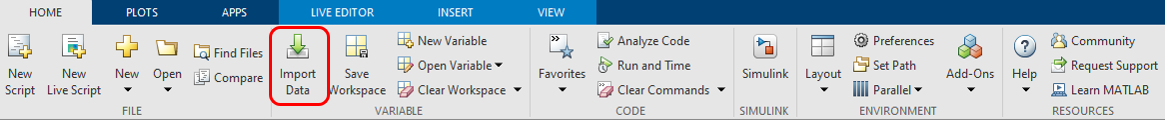

Now you try! Using either the built in GUI or readtable() functionality. Import any populated excel file into the MATLAB environment. Comment on the noted disadvantages/advantages of the selected approach in the space below.

#### Work with Input Data Interactively

Once data has been loaded into a programming environment by the user as an input, the next step is usually to perform some manipulation of the input data as well as to plot visualisations of the data. Using MATLAB, the manipulation of this data can be done by building functions to achieve  a desired output or for common data manipulation algorithms, built-in apps can be used to assist with data manipulation. We will focus on using the MATLAB's Live Editor environment built-in interactive apps to manipulate and visualise data. 

On the MATLAB toolstrip, under the "Live Editor"

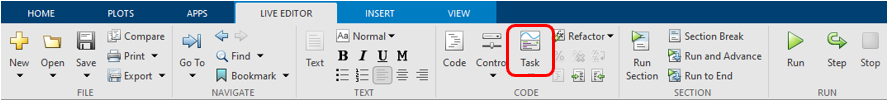

These interactive options allow you to perform different data manipulation function such as  preprocessing and visualize data interactively on  a Live Editor  without the need for calling functions or writing code. In the example below, the "Create Plot" functionality is used to interactively plot a visualisation of a specified dataset that has been loaded. The different section in the functionality allow you to select the input data that has been loaded onto the workspace, chose a suitable visualisation and then a plot a display of the dataset. A full set of the code used to execute this process can be seen by clicking on the triangle at the bottom of the functionality. 

% Create scatter of T.Height and T.Weight
s = scatter(T.Height,T.Weight,'Marker','*','DisplayName','Weight');

% Add xlabel, ylabel, title, and legend
xlabel('Height')
ylabel('Weight')
title('Height vs. Weight')
legend

Now you try! Using the interactive live editor, investigate the data preprocessing options and use the appropriate functionality to normalize the data in the "myExampleTable.xlsx" dataset. Use the space below to document the process and the results obtained. 

## Reading and Writing unstructured data types

Many common programming languages have extensive built-in functionality for reading and writing  structured data types, including MATLAB. However, there are different data structures that are unstructured such as images and audio which can also be specified as an input. In this section we will particularly look at the two common functionalities for reading and writing  images into the MATLAB environment:   [imread](https://www.mathworks.com/help/matlab/ref/imread.html)() and [imwrite](https://www.mathworks.com/help/matlab/ref/imwrite.html)(). Use the MATLAB [documentation](https://www.mathworks.com/help/matlab/) to search how to read other unstructured data types such as [audio](https://www.mathworks.com/help/matlab/ref/audioread.html).

MATLAB provides a comprehensive workflow for image processing, analysis and visualisation. The simplest way to begin this process is by reading in an image that is specified as an input by the user. The imread() function can be used to read in images into the MATLAB environment. This functionality supports image extensions such as .tif, .bmp and .png. More extensions can be found [here](https://www.mathworks.com/help/matlab/ref/imread.html). 

matlabLogo = imread('MATLAB-symbol.jpg');
imshow(matlabLogo)

Hopefully by now you are familiar  with the process once data has been specified as an input by a user - some form of manipulation is done to the data. In this example, we simply manipulate our input by converting our color input image into a black and white image by using the [rgb2gray](https://www.mathworks.com/help/matlab/ref/rgb2gray.html)() functionality. More image processing functionality can be studied [here](https://www.mathworks.com/products/image.html). 

matlabBW = rgb2gray(matlabLogo);
imshow(matlabBW)

Once our image has been manipulated to our liking, we can save the data/image using the [imwrite](https://www.mathworks.com/help/matlab/ref/imwrite.html)() functionality. Note: Images can be created through plots in MATLAB and saved to file. 

imwrite(matlabBW, 'matlabLogoBW.png');

Now you try! Using the MATLAB [documentation](https://www.mathworks.com/help/matlab/), [read](https://www.mathworks.com/help/matlab/ref/audioread.html) in an audio, perform some kind of manipulation on the audio and [write](https://www.mathworks.com/help/matlab/ref/audiowrite.html) the output of the manipulated  audio to file. Comment on the process in the space below.  

## **What we've covered this week**

This week we learnt about,

- Different Input and Output systems 

- Importing data from various structured data types

- Processing data using live tasks

- Importing data from unstructured data types

## **Extra Resources**

- [How to Import Excel Data into MATLAB](https://www.mathworks.com/support/search.html/videos/getting-started-from-excel-97477.html?fq[]=asset_type_name:video&fq[]=category:matlab/spreadsheets&page=1)

- [Data Import and Export](https://www.mathworks.com/help/matlab/data-import-and-export.html?category=data-import-and-export&s_tid=CRUX_topnav) 

- [Preprocessing Data](https://www.mathworks.com/help/matlab/preprocessing-data.html?s_tid=CRUX_lftnav) 

- [Large Files and Big Data ](https://www.mathworks.com/help/matlab/large-files-and-big-data.html?s_tid=CRUX_lftnav)

***Copyright 2022 The MathWorks, Inc. & Opti-Num Solutions (Pty) Ltd.***